# Optical Communications Channel with OOK and DD

The following code simulates the transmitter, channel and reciever of an optical communications system which uses on-off keying and direct detection. The effects of AWGN and CD are investigated.

## Optical Transmitter

The transmitter consists of the following elements:

- Current modulator - which turns the current to a laser on or off depending on the bit sequence to be transferred.

- Laser - which turns on and off depending on the current. The laser linewidth can be varied to analyse the effect of CD.

% A random sequence of source bits is created

SpS = 1; % Samples per symbol
Rs = 1e10; % Symbol rate in symbols/s
NBits = 1000; % No. of bits
NSymb = NBits/SpS; % No. of symbols
sourceBits = randi([0 1], NBits, 1); % Vector of source bits

% The laser current is turned on and off according to the bit sequence

% Laser parameters
laserPw = 10; % Laser power in mW
laserLW = 2; % Laser linewidth in kHz

laserOut = sourceBits*laserPw

laserOut =     10
     0
     0
     0
    10
    10
     0
     0
    10
     0


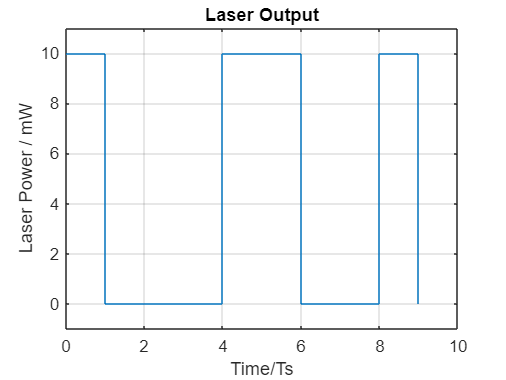


t = [0: 1 : NSymb - 1];
stairs(t(1:10), laserOut(1:10));
title('Laser Output');
xlabel('Time/Ts');
ylabel('Laser Power / mW');
ylim([-1, 11])
grid on

## Optical Channel

The optical channel is modelled to add AWGN and CD

% Optical channel parameters
Z_f = 100; % Impedance of fibre material in Ohms

channelOut = laserOut;

laserOut_CD = ones(NBits,1)*sqrt(laserPW); % Initialising laser output + CD

% % Adding CD
% if laserLW ~= 0 
%     Ts = 1/(SpS*Rs); % Period between samples
% 
%     % Calculating the phase noise:
%     Var = 2*pi*(laserLW*10^3)*Ts;
%     Delta_theta = sqrt(Var)*randn(size(NBits,1),1);
%     Theta = cumsum(Delta_theta);
% 
%     E = E.*repmat(exp(1i*Theta),1,size(E,2)); % Adding phase noise to the optical signal:
% end

## Optical Reciever

The receiver consists of the following elements:

- Photodetector - which outputs a current depending on the magnitude of the electric field it is exposed to

- Transimpedance amplfier (TIA) - which converts the current output from the photodetector to an amplified voltage

- ADC - which samples the output voltage from the TIA

- Decoder - which maps the samples from the ADC to symbols (0 or 1)

% Receiver parameters
eta_ph = 0.3; % Responsivity of photodetector
TIA_gain = 2; % Gain of TIA


% Photodetection process
E = sqrt(2*Z_f*channelOut); % Electric field strength at the output of the fibre
i_ph = eta_ph*E.^2; % Current output from photodetection

Vout = i_ph*TIA_gain;
Vmax = sqrt(2*Z_f*laserPw);



